# **Materials classification - A1**

# image wavelet scattering- PCA

clc; clear all; close all;

## Import dataset

rng(100)

% Training and test images
train_image_data_folder = "Data\Train\image\";
test_image_data_folder = "Data\Test\image\";

imds = imageDatastore(train_image_data_folder, 'IncludeSubFolders',true);
imds = imageDatastore(imds.Files ...
, 'ReadFcn', @demosaic, 'FileExtensions','.jpg','LabelSource','foldernames');

% Imds = imageDatastore(train_image_data_folder,'IncludeSubFolders',true,'FileExtensions','.jpg','LabelSource','foldernames');
% imageSize = [200 200 1];
imds = shuffle(imds);
[trainImds,valImds] = splitEachLabel(imds,0.9);
% trainImds = augmentedImageDatastore(imageSize, trainImds, 'ColorPreprocessing', 'rgb2gray');
% valImds = augmentedImageDatastore(imageSize, valImds, 'ColorPreprocessing', 'rgb2gray');

### Create image set

% The training set consists of 810 images (81 images/ class) and
% the validation set consists of 90 images (9 images/ class)
countEachLabel(trainImds)

ans = 10×2 table
     Label     Count
    _______    _____

    fabric      81  
    foliage     81  
    glass       81  
    leather     81  
    metal       81  
    paper       81  
    plastic     81  
    stone       81  
    water       81  
    wood        81  


countEachLabel(valImds)

ans = 10×2 table
     Label     Count
    _______    _____

    fabric       9  
    foliage      9  
    glass        9  
    leather      9  
    metal        9  
    paper        9  
    plastic      9  
    stone        9  
    water        9  
    wood         9  


Ttrain = tall(trainImds);
Tval = tall(valImds);

### Wavelet image scattering framework

% Create a scattering framework with input image size = 200 x 200 and with an InvarianceScale of 150
sn = waveletScattering2('ImageSize',[200 200],'InvarianceScale',150);

% Extract features for classification for each the training and test sets, use the helperScatImages_mean function
trainfeatures = cellfun(@(x)helperScatImages_mean(sn,x),Ttrain,'Uni',0);
testfeatures = cellfun(@(x)helperScatImages_mean(sn,x),Tval,'Uni',0);

% Gather all the training and test feature vectors and concatenate them into matrices.
Trainf = gather(trainfeatures);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 7 min 42 sec
Evaluation completed in 7 min 42 sec


trainfeatures = cat(2,Trainf{:});
Testf = gather(testfeatures);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 51 sec
Evaluation completed in 51 sec


testfeatures = cat(2,Testf{:});

model = helperPCAModel(trainfeatures,30,trainImds.Labels);
predlabels = helperPCAClassifier(testfeatures,model);

accuracy = sum(valImds.Labels == predlabels)./numel(valImds.Labels)*100

accuracy = 25.5556

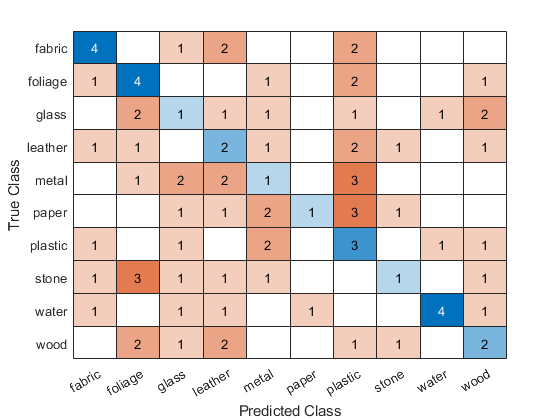


figure
confusionchart(valImds.Labels,predlabels)

## Helper functions

function output = demosaic(inputFilename)
input = imread(inputFilename);
output = im2gray(input);
end

function features = helperScatImages_mean(sf,x)
x = imresize(x,[200 200]);
    smat = featureMatrix(sf,x);
    features = mean(mean(smat,2),3);
end


function model = helperPCAModel(features,M,Labels)
% This function is only to support wavelet image scattering examples in 
% Wavelet Toolbox. It may change or be removed in a future release.
% model = helperPCAModel(features,M,Labels)

% Copyright 2018 MathWorks

% Initialize structure array to hold the affine model
model = struct('Dim',[],'mu',[],'U',[],'Labels',categorical([]),'s',[]);
model.Dim = M;
% Obtain the number of classes
LabelCategories = categories(Labels);
Nclasses = numel(categories(Labels));
for kk = 1:Nclasses
    Class = LabelCategories{kk};
    % Find indices corresponding to each class
    idxClass = Labels == Class;
    % Extract feature vectors for each class
    tmpFeatures = features(:,idxClass);
    % Determine the mean for each class
    model.mu{kk} = mean(tmpFeatures,2);
    [model.U{kk},model.S{kk}] = scatPCA(tmpFeatures);
    if size(model.U{kk},2) > M
        model.U{kk} = model.U{kk}(:,1:M);
        model.S{kk} = model.S{kk}(1:M);
    end
    model.Labels(kk) = Class;
end

function [u,s,v] = scatPCA(x,M)
	% Calculate the principal components of x along the second dimension.

	if nargin > 1 && M > 0
		% If M is non-zero, calculate the first M principal components.
	    [u,s,v] = svds(x-sig_mean(x),M);
	    s = abs(diag(s)/sqrt(size(x,2)-1)).^2;
	else
		% Otherwise, calculate all the principal components.
        % Each row is an observation, i.e. the number of scattering paths
        % Each column is a class observation
		[u,d] = eig(cov(x'));
		[s,ind] = sort(diag(d),'descend');
		u = u(:,ind);
	end
end
end

function labels = helperPCAClassifier(features,model)
% This function is only to support wavelet image scattering examples in 
% Wavelet Toolbox. It may change or be removed in a future release.
% model is a structure array with fields, M, mu, v, and Labels
% features is the matrix of test data which is Ns-by-L, Ns is the number of
% scattering paths and L is the number of test examples. Each column of
% features is a test example.

% Copyright 2018 MathWorks

labelIdx = determineClass(features,model); 
labels = model.Labels(labelIdx); 
% Returns as column vector to agree with imageDatastore Labels
labels = labels(:);


%--------------------------------------------------------------------------
function labelIdx = determineClass(features,model)
% Determine number of classes
Nclasses = numel(model.Labels);
% Initialize error matrix
errMatrix = Inf(Nclasses,size(features,2));
for nc = 1:Nclasses
    % class centroid
    mu = model.mu{nc};
    u = model.U{nc};
    % 1-by-L
    errMatrix(nc,:) = projectionError(features,mu,u);
end
% Determine minimum along class dimension
[~,labelIdx] = min(errMatrix,[],1);   


%--------------------------------------------------------------------------
function totalerr = projectionError(features,mu,u)
    %
    Npc = size(u,2);
    L = size(features,2);
    % Subtract class mean: Ns-by-L minus Ns-by-1
    s = features-mu;
    % 1-by-L
    normSqX = sum(abs(s).^2,1)';
    err = Inf(Npc+1,L);
	err(1,:) = normSqX;
    err(2:end,:) = -abs(u'*s).^2;
    % 1-by-L
    totalerr = sqrt(sum(err,1));
end
end
end
